# Interferometro de Mach Zehnder

El objetivo es simular el funcionamiento del interferometro.

clear;
clc;

% Ventana numerica
N = 256;
w0 = 1E-3;    % [m]
xmax = 3*w0;
lambda = 633E-9;   % [m]
xs = xmax*(2/N)*(-N/2:N/2-1);
ys = xmax*(2/N)*(-N/2:N/2-1);
[Xs, Ys] = meshgrid(xs, ys);

El haz que entrara al inteferometro es un haz Gaussiano

$U(x,y) = \exp\left[-(x^2 + y^2)/w_0^2\right]$,

donde $w_0$ es la cintura en $z=0$.  Ademas el haz se encuentra tambien en $z=0$.

GB = @(X,Y,w) exp(-(X.^2 + Y.^2)/w^2)

GB = function_handle with value:
    @(X,Y,w)exp(-(X.^2+Y.^2)/w^2)


Ademas es conveniente definir la matriz correspondiente al divisor.

BS = (1/sqrt(2))*[1 1i; 1i 1]

BS =    0.7071 + 0.0000i   0.0000 + 0.7071i
   0.0000 + 0.7071i   0.7071 + 0.0000i


% semilla
U = GB(Xs, Ys, w0);
umax = max(abs(U(:)).^2);

% Primer divisor
E3 = BS(1,1)*U + BS(1,2)*0;
E4 = BS(2,1)*U + BS(2,2)*0;

% Espejos
E5 = exp(1i*pi)*E4;
E6 = exp(1i*pi)*E3;

% Placa de vidrio
placa = 0.0;     % (2*pi/lambda)*n*d
E5(N/2:end, :) = exp(1i*placa) * E5(N/2:end, :);

% Vector de propagacion -- up
k = 2*pi/lambda;
thzu = 0.05*(pi/180);
thTu = 0.0;
kxu = k * sin(thzu) * cos(thTu);
kyu = k * sin(thzu) * sin(thTu);
kzu = k * cos(thzu);

% Vector de propagacion -- down
k = 2*pi/lambda;
thzd = -thzu;
thTd = 0.0;
kxd = k * sin(thzd) * cos(thTd);
kyd = k * sin(thzd) * sin(thTd);
kzd = k * cos(thzd);

z=0;
E5 = exp(1i*(kxu*Xs + kyu*Ys + kzu*z))  .* E5;
E6 = exp(1i*(kxd*Xs + kyd*Ys + kzd*z))  .* E6;

% Lente delgada
foco = -1;   % [m]
lente = (k/(2*foco)) * (Xs.^2 + Ys.^2);
%E5 = exp(1i*lente) .* E5;

% Segundo divisor
E7 = BS(1,1)*E5 + BS(1,2)*E6;
E8 = BS(2,1)*E5 + BS(2,2)*E6;

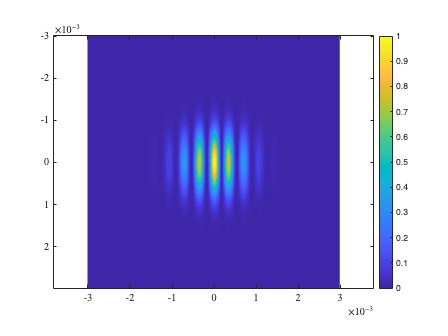

imagesc(xs, ys, abs(E7).^2), clim([0.0 umax]), axis equal, colorbar;

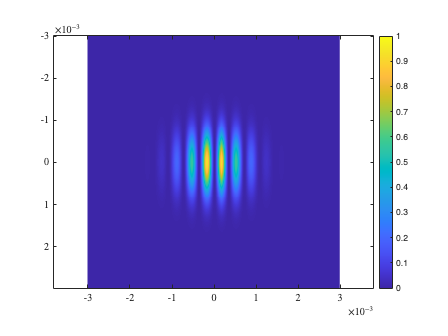

imagesc(xs, ys, abs(E8).^2), clim([0.0 umax]), axis equal, colorbar;

clf

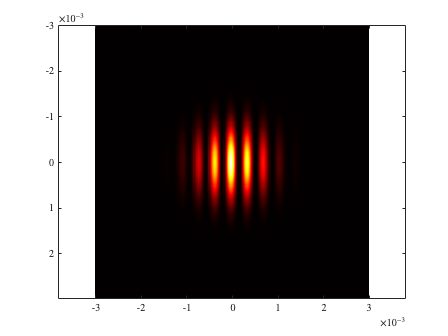

% cantidad de iteraciones
NT = 256;

for ii=1:NT
    % semilla
    U = GB(Xs, Ys, w0);
    umax = max(abs(U(:)).^2);
    
    % Primer divisor
    E3 = BS(1,1)*U + BS(1,2)*0;
    E4 = BS(2,1)*U + BS(2,2)*0;
    
    % Espejos
    E5 = exp(1i*pi)*E4;
    E6 = exp(1i*pi)*E3;
    
    % Vibraciones mecanicas
    n=1;   % indice del medio
    distancia_aleatoria = (1*1E-7)*rand;
    camino = (2*pi/lambda)*n*distancia_aleatoria;
    E5 = exp(1i*camino) * E5;
    
    % Vector de propagacion -- up
    k = 2*pi/lambda;
    thzu = 0.05*(pi/180);
    thTu = 0.0;
    kxu = k * sin(thzu) * cos(thTu);
    kyu = k * sin(thzu) * sin(thTu);
    kzu = k * cos(thzu);
    
    % Vector de propagacion -- down
    k = 2*pi/lambda;
    thzd = -thzu;
    thTd = 0.0;
    kxd = k * sin(thzd) * cos(thTd);
    kyd = k * sin(thzd) * sin(thTd);
    kzd = k * cos(thzd);
    
    z=0;
    E5 = exp(1i*(kxu*Xs + kyu*Ys + kzu*z))  .* E5;
    E6 = exp(1i*(kxd*Xs + kyd*Ys + kzd*z))  .* E6;
    
    % Segundo divisor
    E7 = BS(1,1)*E5 + BS(1,2)*E6;
    E8 = BS(2,1)*E5 + BS(2,2)*E6;

    imagesc(xs,ys,abs(E7).^2), axis equal, clim([0.0, umax]), colormap hot;
    pause(0.01);
end

% semilla
U = GB(Xs, Ys, w0);
umax = max(abs(U(:)).^2);

% Primer divisor
E3 = BS(1,1)*U + BS(1,2)*0;
E4 = BS(2,1)*U + BS(2,2)*0;

% Espejos
E5 = exp(1i*pi)*E4;
E6 = exp(1i*pi)*E3;

% Placa de vidrio
placa = 0.0;     % (2*pi/lambda)*n*d
E5(N/2:end, :) = exp(1i*placa) * E5(N/2:end, :);

% Vector de propagacion -- up
k = 2*pi/lambda;
thzu = 0.05*(pi/180);
thTu = 0.0;
kxu = k * sin(thzu) * cos(thTu);
kyu = k * sin(thzu) * sin(thTu);
kzu = k * cos(thzu);

% Vector de propagacion -- down
k = 2*pi/lambda;
thzd = -thzu;
thTd = 0.0;
kxd = k * sin(thzd) * cos(thTd);
kyd = k * sin(thzd) * sin(thTd);
kzd = k * cos(thzd);
z=0;
E5 = exp(1i*(kxu*Xs + kyu*Ys + kzu*z))  .* E5;
E6 = exp(1i*(kxd*Xs + kyd*Ys + kzd*z))  .* E6;

% Segundo divisor (solamente la salida 7)
% El campo en la salida 7 numericamente esta representado por EX, EY
EX = (1/sqrt(2))*E5;
EY = (1/sqrt(2))*E6;

% Medicion de los parametros de Stokes
S0 = abs(EX).^2 + abs(EY).^2;
S1 = abs(EX).^2 - abs(EY).^2;
S2 = 2*real(EX .* conj(EY));   % o implementado las matrices de Jones correspondientes
S3 = 2*imag(EX .* conj(EY));

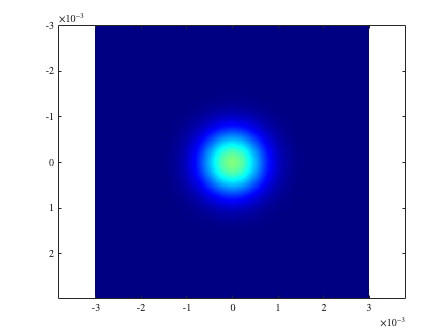

imagesc(xs,ys,S0), axis equal, clim([0.0, umax]), colormap jet;

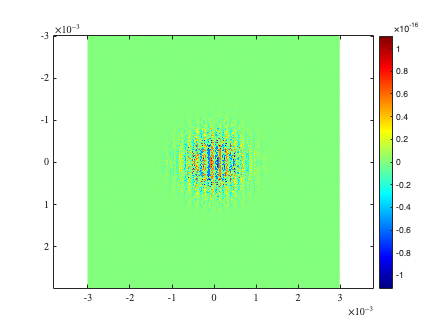

imagesc(xs,ys,S1), axis equal, colormap jet, colorbar;

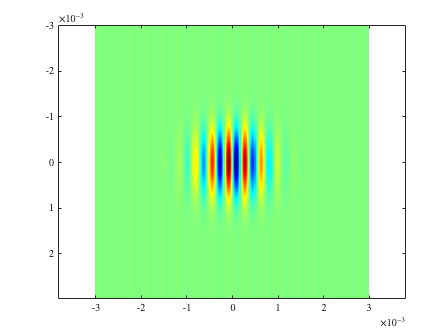

imagesc(xs,ys,S2), axis equal, colormap jet;

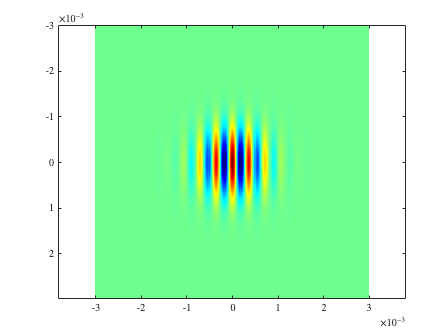

imagesc(xs,ys,S3), axis equal, colormap jet;

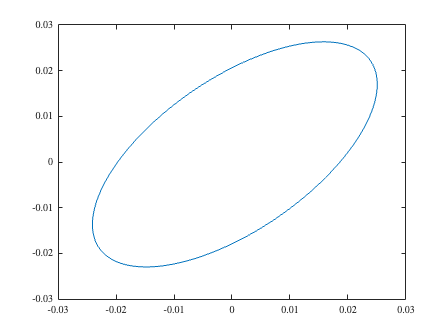

elipseX = @(th, x0, Emax, Emin, alfa) Emax*cos(alfa)*cos(th) - Emin*sin(alfa)*sin(th) + x0;
elipseY = @(th, y0, Emax, Emin, alfa) Emax*cos(alfa)*sin(th) - Emin*sin(alfa)*cos(th) + y0;

th = linspace(0.0, 2*pi, 128);

Emax = sqrt(0.5*(S0 + sqrt(S1.^2 + S2.^2)));
Emin = sqrt(0.5*(S0 - sqrt(S1.^2 + S2.^2)));
alfa = 0.5*atan2(S2,S1);

XE = elipseX(th, Xs(200,150), Emax(200,150), Emin(200,150), alfa(200,150));
YE = elipseY(th, Ys(200,150), Emax(200,150), Emin(200,150), alfa(200,150));

plot(XE, YE)